v = VideoReader("RoadTraffic.mp4")

v =   VideoReader with properties:

   General Properties:
            Name: 'RoadTraffic.mp4'
            Path: 'C:\Users\Asad PC\Documents\MATLAB\Image Processing for Engineering and Science\Data\MathWorks Images'
        Duration: 24
     CurrentTime: 0.1000
       NumFrames: 240

   Video Properties:
           Width: 1158
          Height: 518
       FrameRate: 10
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


function I_denoised = enhanceImage(img)
    
    I_gray = im2gray(img);

    I_denoised = imgaussfilt(I_gray, 2);

end

function [BW,maskedImage] = segmentImage(X)
    BW = im2gray(X) > 1.269600e-01;
    BW = imfill(BW, 'holes');
    
    radius = 27;
    decomposition = 0;
    se = strel('disk', radius, decomposition);
    BW = imclose(BW, se);
    
    maskedImage = X;
    maskedImage(~BW) = 0;
end

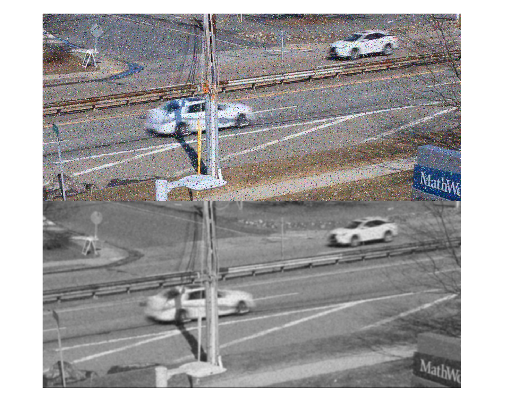

frame = read(v, 10);
frame_enhanced = enhanceImage(frame);
montage({frame, frame_enhanced})

frameSum = im2double(read(v, 1));

for idx = 2:v.NumFrames
    frameSum = frameSum + im2double(read(v, idx));
end

avgFrame = frameSum / v.NumFrames;


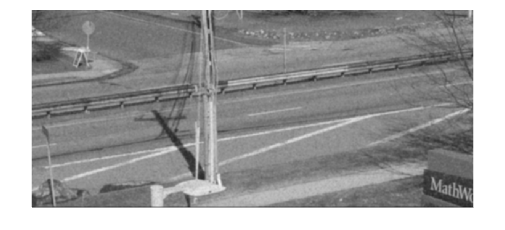

enhancedBg = enhanceImage(avgFrame);
imshow(enhancedBg)

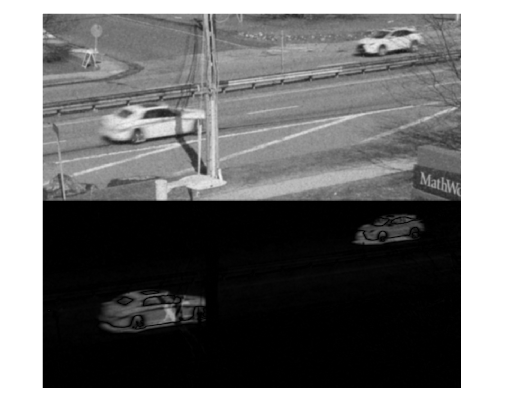

frame_6 = im2double(enhanceImage(read(v, 9)));
frameDiff = abs(frame_6 - enhancedBg);

montage({frame_6, frameDiff})

numFrames = v.NumFrames;
numRegions = zeros(numFrames,1);
meanRegionSize = zeros(numFrames,1);
totalRegionSize = zeros(numFrames,1);

for idx = 1:numFrames
    % Read and enhance the current frame
    currentFrame = read(v, idx);
    enhancedFrame = enhanceImage(currentFrame);
    enhancedFrame = im2double(enhancedFrame);
    
    % Subtract background
    fg = imabsdiff(enhancedFrame, enhancedBg);

    % Segment foreground (cars)
    [BW, ~] = segmentImage(fg);

    % Analyze connected components
    stats = regionprops(BW, 'Area');
    areas = [stats.Area];
    
    % Filter out small regions (< 1000)
    carAreas = areas(areas >= 1000);
    
    % Store stats for valid car regions
    numRegions(idx) = numel(carAreas);
    totalRegionSize(idx) = sum(carAreas);
    
    if ~isempty(carAreas)
        meanRegionSize(idx) = mean(carAreas);
    else
        meanRegionSize(idx) = 0;
    end
end

% Create table
frameStats = table((1:numFrames)', numRegions, meanRegionSize, totalRegionSize, ...
                   'VariableNames', {'Frame', 'NumRegions', 'MeanRegionSize', 'TotalRegionSize'});

% Display table
disp(frameStats)

    Frame    NumRegions    MeanRegionSize    TotalRegionSize
    _____    __________    ______________    _______________

       1         0                  0                 0     
       2         0                  0                 0     
       3         0                  0                 0     
       4         0                  0                 0     
       5         0                  0                 0     
       6         2               5158             10316     
       7         2              14030             28060     
       8         2              19460             38919     
       9         2              18345             36690     
      10         2              18222             36445     
      11         2              17805             35610     
      12         2              17748             35496     
      13 

numFramesWithCars = sum(frameStats.NumRegions > 0);
fprintf('Number of frames with at least one detected car: %d\n', numFramesWithCars);

Number of frames with at least one detected car: 155


modeNumCars = mode(numRegions);

fprintf('The mode value for the number of cars detected per frame is: %d\n', modeNumCars);

The mode value for the number of cars detected per frame is: 1


averageRegionSize = sum(frameStats.TotalRegionSize) / sum(frameStats.NumRegions);
fprintf('Average region size across the entire video: %.2f pixels\n', averageRegionSize);

Average region size across the entire video: 17275.35 pixels


% Set up video writer
outputVideo = VideoWriter('RoadTraffic_Annotated.mp4', 'MPEG-4');
outputVideo.FrameRate = v.FrameRate;
open(outputVideo);

for idx = 1:numFrames
    % Read and enhance the current frame
    currentFrame = read(v, idx);
    enhancedFrame = enhanceImage(currentFrame);
    enhancedFrame = im2double(enhancedFrame);
    
    % Subtract background
    fg = imabsdiff(enhancedFrame, enhancedBg);

    % Segment foreground (cars)
    [BW, ~] = segmentImage(fg);

    % Analyze connected components
    stats = regionprops(BW, 'Area', 'BoundingBox');

    % Filter out small regions (< 1000) and get their bounding boxes
    validStats = stats([stats.Area] >= 1000);
    bboxes = reshape([validStats.BoundingBox], 4, [])';

    % Insert bounding boxes into original RGB frame
    if ~isempty(bboxes)
        annotatedFrame = insertShape(currentFrame, 'Rectangle', bboxes, ...
                                     'Color', 'green', 'LineWidth', 2);
    else
        annotatedFrame = currentFrame;
    end
    
    % Write frame to output video
    writeVideo(outputVideo, annotatedFrame);
end

% Finalize video
close(outputVideo);

fprintf('Annotated video with bounding boxes saved as: RoadTraffic_Annotated.mp4\n');

Annotated video with bounding boxes saved as: RoadTraffic_Annotated.mp4
